# **InverseJacobiDS**

[Inverse of the Jacobi elliptic function ds](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{ds}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(\frac{1}{\sqrt{m+x^2 }}\left|m\right.\right) & m\le 1\\
\frac{{\textrm{cs}}^{-1} \left(x/\sqrt{m}\left|m^{-1} \right.\right)}{\sqrt{m}} & m>1
\end{array}\right.$$



$${\mathrm{ds}}^{-1} \left(x,k\right)\equiv {\mathrm{ds}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parmeter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  Jacobi form of the elliptic integral of the first kind.

Domain:   If $-\infty <m\le 1$ then $\left|x\right|>\sqrt{1-m}$ . If $m>1$ then $-\infty \le x\le \infty$.For the specified domain, the  codomain  is the set of real numbers.

Basic features:

${\mathrm{ds}}^{-1} \left(-x\left|m\right.\right)=-{\mathrm{ds}}^{-1} \left(x\left|m\right.\right)$   (odd)

Special values:

   ${\mathrm{ds}}^{-1} \left(0\left|m\right.\right)=\mathrm{NaN}$,    ${\textrm{ds}}^{-1} \left(\pm \infty \left|m\right.\right)=0$

${\mathrm{ds}}^{-1} \left(x\left|0\right.\right)={\mathrm{csc}}^{-1} x$,    ${\mathrm{ds}}^{-1} \left(x\left|1\right.\right)={\mathrm{csch}}^{-1} x$

Identities:


$${\mathrm{ds}}^{-1} \left(\mathrm{ds}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{ds}\left({\textrm{ds}}^{-1} \left(x\left|m\right.\right)\left|m\right.\right)=x$$


$K\left(m\right)$ is the complete elliptic integral of the first kind.

## Syntax

Y = InverseJacobiDS(X,K)

y = ijds(x,k)

Y = mInverseJacobiDS(X,M)

y = mijds(x,m)

## Dedsription

**Y = InverseJacobiDS(X,K)** return${\;\mathrm{ds}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the sdse size or any of them can be dsalar. **InverseJacobiDS** is the wrapper function which calls the functions **ijds** element-wise via the function **ufun2**.

**y = ijds(x,k)** return the value of ${\mathrm{ds}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real dsalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **ijds** is the wrapper function which calls the functions **mijds**.

**Y = mInverseJacobiDS(X,M)** returns ${\mathrm{ds}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (pardseter). X and M must be real and the sdse size or any of them can be dsalar. **mInverseJacobiDS** is the wrapper function which calls the functions **mijds** element-wise via the function **ufun2**.

**y = mijds(x,m)** compute value of $\mathrm{ds}\left(x\left|m\right.\right)$ for  argument x and the pardseter m. It is assumed that the input arguments are real dsalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijds **call the function **melF **for calculation of ${\mathrm{ds}}^{-1} \left(x\left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 1.5;
[ijds(x,k), InverseJacobiDS(x,k), mijds(x,k^2), mInverseJacobiDS(x,k^2)]

ans =    0.697496312684765   0.697496312684765   0.697496312684765   0.697496312684765


% Maple 2.85977139929949528  %% WRONG VALUE


Accuracy.

fprintf('%.16g\n',mijds(0.5,-4)) 

NaN


%  Maple  Fail to calculate 

Special values

m=0.5;
disp(mijds(0,m))  % m < 1 !!!

   NaN



x=0.5;
disp(mijds(x,0) - acsc(x)) 

                NaN + 1.316957896924817i



disp(mijds(x,1) - acsch(x))

     0



Identities

m = -2;
x = 0.5; % |x| <= 1
disp(mJacobiDS(mInverseJacobiDS(x,m),m)-x)

   NaN




k = 0.99995;
x = 0.9999*elK(k); % |x|<K
disp(InverseJacobiDS(JacobiDS(x,k),k)-x)

     3.389999392311438e-11



m = 2; % m>1
x = 10.2; 
disp(mijds(x,m)-mijcs(x/sqrt(m),1/m)/sqrt(m))

     0



m = 0.5;
x = 0.2;
disp(mijds(-x,m)+mijds(x,m))

   NaN



**Vector input**

m = [0.1, 0.5, 0.89, 0.99995];
x = 0.2*ones(size(m));
disp(mJacobiDS(mInverseJacobiDS(x,m),m)-x)

   1.0e-15 *

                 NaN                 NaN                 NaN  -0.638378239159465



**Matrix input**

m = [0.1, 0.5, 0.89; -1, -97, 0.99995 ]';
x = 0.2*ones(size(m));
disp(mJacobiDS(mInverseJacobiDS(x,m),m)-x)

   1.0e-15 *

                 NaN                 NaN
                 NaN                 NaN
                 NaN  -0.638378239159465



## **Plot **

**Example 1**

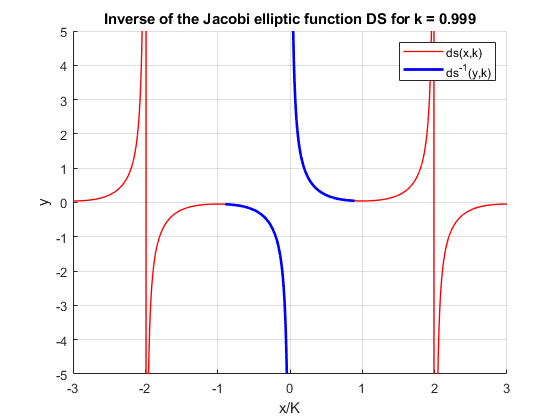

figure
hold on
x=-3:0.01:3;
k = 0.999;
M = elK(k);
plot(x,JacobiDS(M*x,k),'LineWidth',1.0,'Color','red')
x=-102:0.01:102;
plot(InverseJacobiDS(x,k)/M,x,'LineWidth',2,'Color','blue')
legend('ds(x,k)','ds^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function DS for k = %g',k))
grid on
hold off

**Example 2**

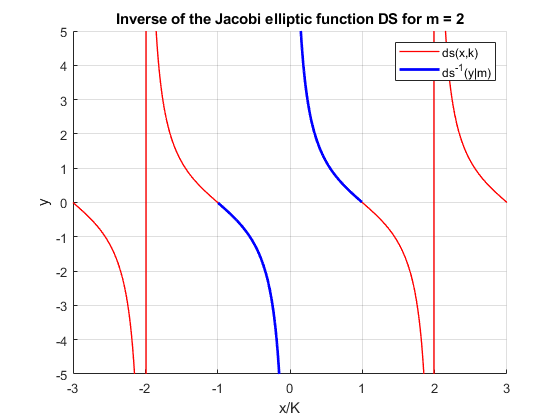

figure
hold on
x=-3:0.01:3;
m = 2;
if m < 1
    M = melK(m);
    xlabel('x/K')
elseif m > 1
    M = melK(1/m)/sqrt(m);
    xlabel('x/K')
else
    M = 1;
    xlabel('x')
end
plot(x,mJacobiDS(M*x,m),'LineWidth',1.0,'Color','red')
x=-102:0.01:102;
plot(mInverseJacobiDS(x,m)/M,x,'LineWidth',2,'Color','blue')
legend('ds(x,k)','ds^{-1}(y|m)') %,'Position','best')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function DS for m = %g',m))
grid on
hold off

**Example 2**

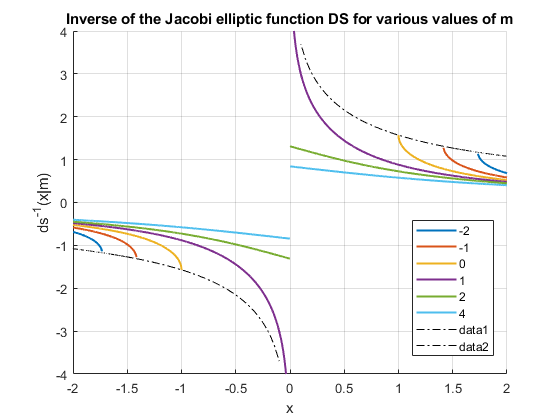

figure
hold on
X = -2:0.001:2;
M = [-2,-1,0,1,2,4];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiDS(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -4 4])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function DS for various values of m')
N=-400:0.01:1;
X = sqrt(1-N);
plot(X,mInverseJacobiDS(X,N),'k-.')
plot(-X,-mInverseJacobiDS(X,N),'k-.')
xlabel('x')
ylabel('ds^{-1}(x|m)')

**Example 3**

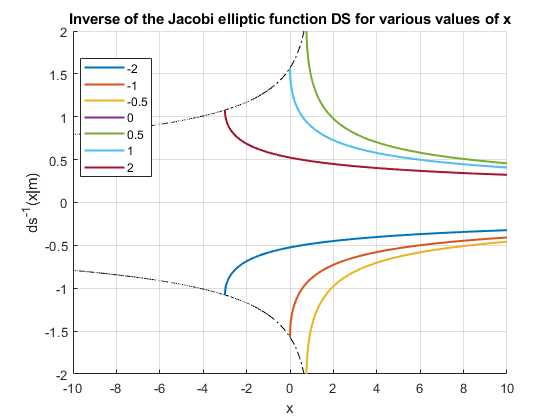

figure
hold on
M = -10:0.01:10;
X = [-2,-1,-0.5,0,0.5,1,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiDS(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
ylim([-2  2])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function DS for various values of x')
xlabel('x')
ylabel('ds^{-1}(x|m)')
M = -200:0.01:1;
F = mInverseJacobiDS(sqrt(1-M),M);
plot(M,F,'k-.')
plot(M,-F,'k-.')
hold off

**Example 4**

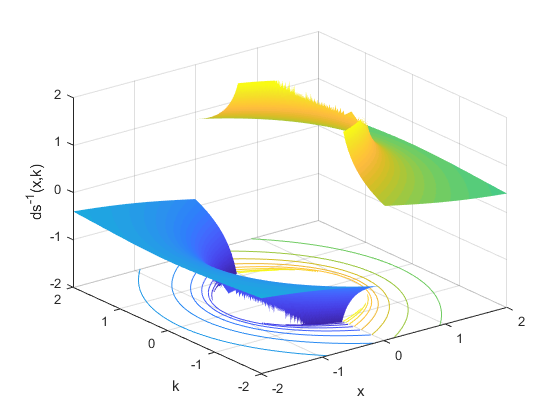

figure
x=-2:0.01:2;
k=-2:0.01:2;
zz = 2;
[X,M]=meshgrid(x,k);
hs=surfc(X,M,InverseJacobiDS(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -zz;
hc.LineWidth = 0.5;
hc.LevelList = -zz:zz/10:zz;
view(3)
caxis([-zz zz])
xlabel('x')
ylabel('k')
zlabel('ds^{-1}(x,k)')
zlim([-zz zz])
grid on

**Example 4**

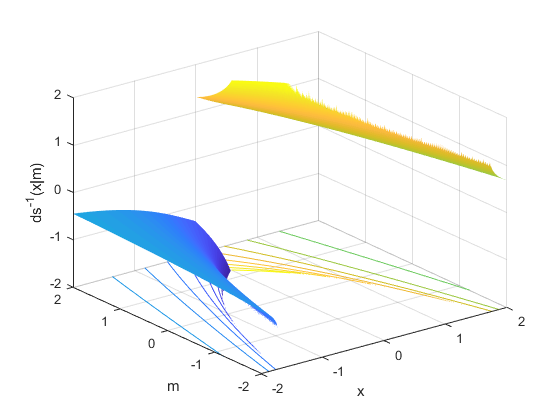

figure
x=-2:0.01:2;
m=-2:0.01:2;
zz = 2;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiDS(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -zz;
hc.LineWidth = 0.5;
hc.LevelList = -zz:zz/10:zz;
view(3)
caxis([-zz zz])
xlabel('x')
ylabel('m')
zlabel('ds^{-1}(x|m)')
zlim([-zz zz])
grid on

**Example 5**

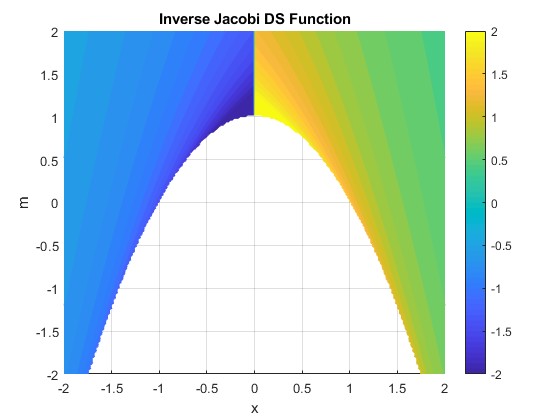

figure
f = @(x,m)mInverseJacobiDS(x,m);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi DS Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 6**

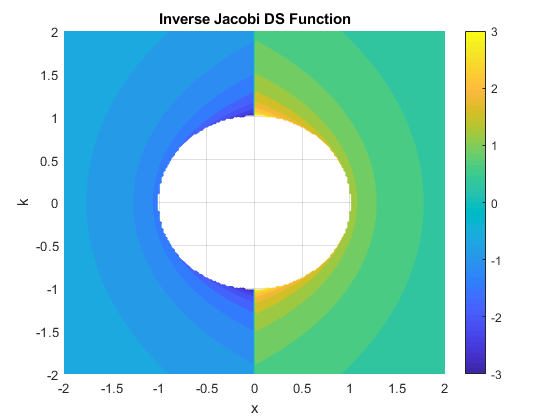

figure
f = @(x,k)InverseJacobiDS(x,k);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi DS Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

## See Also